%% Self-Balancing Reaction Wheel Robot: True Physical Model

clear all; close all; clc;

Mm = 0.231; % [kg] motor mass
Mb = 0.4; % structure mass
Mr = 0.100; % rotor mass

lm = 0.09; % [m]
lb = 0.09;
lr = lm;

g = 9.81; % [m/s2]

k_mgl = g * (Mm*lm + Mb*lb + Mr*lr)

k_mgl = 0.6454


Iro = Mr*lr^2 % rotor inertia

Iro = 8.1000e-04

Imo = Mm*lm^2 % motor "

Imo = 0.0019

Ibo = Mb*lb^2 % struct "

Ibo = 0.0032


Iso = Iro + Imo + Ibo % total intertia about o

Iso = 0.0059


tau_m = 0.1; % [s] control loop response time to motor speed input on odrive

dt = 0.01;  % Sampling time [s]

%% State-Space Model
% States: x = [theta, theta_d, omega_m]
% Input: u = commanded motor speed, w_mc

A = [0                1                 0;
     k_mgl/Iso        0               -Iro/(Iso*tau_m);
     0                0                 -1/tau_m];

B = [0;
     Iro/(Iso*tau_m);
     1/tau_m];

C = eye(3);  % We can measure all states
D = zeros(3, 1);

% Discretize
sys_c = ss(A, B, C, D);
sys_d = c2d(sys_c, dt, 'zoh');
Ad = sys_d.A

Ad =     1.0055    0.0100   -0.0001
    1.0920    1.0055   -0.0130
         0         0    0.9048


Bd = sys_d.B

Bd =     0.0001
    0.0130
    0.0952



%% LQR Design
Q = diag([1000, 100, 1]);  % High cost on angle and angular velocity
R = 10;  % Cost on motor voltage (control effort)

[K, P, e] = dlqr(Ad, Bd, Q, R);

disp('LQR Gain:');

LQR Gain:


disp(K);

  303.4890   29.1944   -1.9409



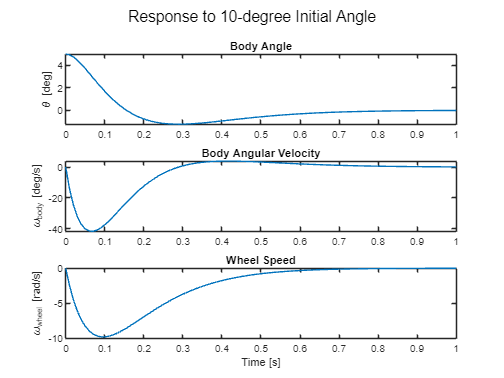


%% Simulate
t = 0:dt:5;
x0 = [5*pi/180; 0; 0];  % 10 degrees initial tilt

% Closed-loop system
sys_cl = ss(Ad - Bd*K, Bd, C, D, dt);

% Simulate
[y, t] = initial(sys_cl, x0, t);

% Plot
figure;
subplot(3,1,1);
plot(t, y(:,1)*180/pi); ylabel('\theta [deg]'); title('Body Angle');
xlim([0 1])
subplot(3,1,2);
plot(t, y(:,2)*180/pi); ylabel('\omega_{body} [deg/s]'); title('Body Angular Velocity');
xlim([0 1])
subplot(3,1,3);
plot(t, y(:,3)); ylabel('\omega_{wheel} [rad/s]'); title('Wheel Speed');
xlim([0 1])
xlabel('Time [s]');
sgtitle('Response to 10-degree Initial Angle');